clear;
clc;

%导入训练集数据
label=importdata("label_directions.mat");   %上\下\右\左\眨眼
up=importdata("up_wavelet_features_1218.mat");
down=importdata("down_wavelet_features_1218.mat");
right=importdata("right_wavelet_features_1218.mat");
left=importdata("left_wavelet_features_1218.mat");
wink=importdata("wink_wavelet_features_1218.mat");
dataset=[up;down;right;left;wink];
dataset=real(dataset);      %数据集数据不能为复数
%dataset=normalize(dataset,'range');
%DATABASE=[dataset,label];

%训练模型
n=1000

n = 1000

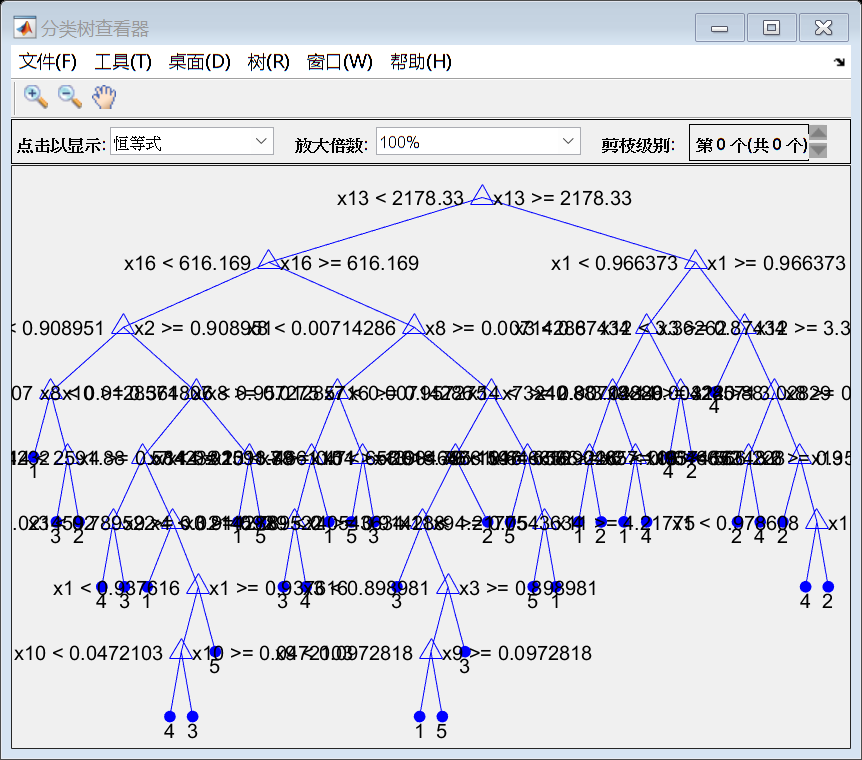

model = TreeBagger(n, dataset, label, Method="classification");
view(model.Trees{n},'Mode','graph')

%% 调用javaRobot类
javaaddpath('E:\桌面\srtp眼电\代码们\鼠标控制\jdk-17\bin')  %文件相对路径
import java.awt.Robot;
import java.awt.event.*;
import java.awt.event.InputEvent;
% 创建Robot对象
robot = Robot();

%% 读取数据三个文件（可能之后做动态实验时这一部分代码要改）
fid0=fopen('EOG1.txt');   
c0=textscan(fid0,'%s %s %d %{hh:mm:ss}T %s %d %f');
fclose(fid0);

%c1为第二个信道数据  
fid1=fopen('EOG2.txt');   
c1=textscan(fid1,'%s %s %d %{hh:mm:ss}T %s %d %f');
fclose(fid1);

eog1=c0{1,7};
eog2=c1{1,7};
eog=hampel([eog1,eog2]);
eog=eog(400000:600000,:);
%eeg1,eeg{:,1}为第一信道，eeg2,eeg{:,2}为第二信道

%% 设置一些读取数据的参数
frame_T=10;        %在数据上框选子数据的频率
frame_move=50;     %节选框每次移动的距离
frame_length=700;  %框的大小
frame_energy=0.5;    %眼动能量达到此阈值才开始启动模型（范围是0-1）
frame_interval=1.5;%识别得到一个指令信号后，为了防止同一个指令动作被反复识别，间隔多长时间重新开始裁剪数据

mouse_T=10;        %鼠标每秒移动的次数
mouse_move=10;     %鼠标每次移动的距离

level = 5; % 小波变换的层数，可根据实际情况调整
wname = 'db4'; % 小波类型，可根据实际情况选择
alpha=1.5;%阈值倍数

%% 主程序
start=30000;%从eeg的start位置开始裁剪数据
j=0;
preHistory=[];
while true
    j=j+1;
    %函数function [cut_data, time] = cutEOG(eeg, start, frame_T, frame_move, frame_length, frame_energy)
    %寻找满足能量大于frame_energy的长frame_length的片段
    %cut_data是符合条件的裁剪数据，time为此片段在eeg上的位置（初始位置和终止位置）
    %如果没有符合条件的数据，time返回[-1,-1];cut_data返回[-1,-1]
    [cut_data, time] = cutEOG(eog, start, frame_T, frame_move, frame_length, frame_energy);
    
    %更新时间
    start=time(1,2);
    
    %function wavelet_data=WaveLet(cut_data, level, wname, alpha)
    %小波变换，返回滤波后的数据
    
    wavelet_data=WaveLet(cut_data, level, wname, alpha);
    
    %function features_data=Features(wavelet_data)
    %提取裁剪信号的特征值
    %最后的得到的features_data为一行18个特征值的数据
    
    features_data=real(Features(wavelet_data));
    %features_data=real(Features(cut_data));

    %放入机器学习模型：
    %label_pre=1;
    label_pre=str2num(char(cell2mat(model.predict(features_data))));
    [predict_label,scores] = predict(model, features_data)
    
    preHistory=[preHistory label_pre];
   

    %根据预测得到的标签执行程序
    switch label_pre
        case 1
            i=5;
            %向上移动
            while i>0
                  % 获取当前鼠标位置
                  mouseInfo = java.awt.MouseInfo.getPointerInfo();
                  mouseLocation = mouseInfo.getLocation();
                  x = mouseLocation.getX();
                  y = mouseLocation.getY();
                  % 将鼠标向上移动mouse_move个像素
                  robot.mouseMove(x, y-mouse_move);
                  
                  %等待1/mouse_T，以免移动过快
                  pause(1/mouse_T);
                  
%                   %识别反向停止标签
%                   [cut_data, time] = cutEOG(eog, start, frame_T, frame_move, frame_length, frame_energy);
%                   start=time(1,2);
%                   wavelet_data=WaveLet(cut_data, level, wname, alpha);
%                   features_data=Features(wavelet_data);
%                   %放入机器学习模型：
%                   %label_pre=2;
%                   label_pre=str2num(char(cell2mat(model.predict(features_data))));
% 
%                   %停止信号
%                   if label_pre==2
%                       break;
%                   end
                i=i-1;
            end

        case 2
            i=5;
            %向下移动
            while i>0
                  % 获取当前鼠标位置
                  mouseInfo = java.awt.MouseInfo.getPointerInfo();
                  mouseLocation = mouseInfo.getLocation();
                  x = mouseLocation.getX();
                  y = mouseLocation.getY();
                  % 将鼠标向下移动mouse_move个像素
                  robot.mouseMove(x, y+mouse_move);
                  
                  %等待1/mouse_T，以免移动过快
                  pause(1/mouse_T);
                  
%                   %识别反向停止标签
%                   [cut_data, time] = cutEOG(eog, start, frame_T, frame_move, frame_length, frame_energy);
%                   start=time(1,2);
%                   wavelet_data=WaveLet(cut_data, level, wname, alpha);
%                   features_data=real(Features(wavelet_data));
%                   %放入机器学习模型：
%                   %label_pre=1;
%                   label_pre=str2num(char(cell2mat(model.predict(features_data))));
%                   
%                   %停止信号
%                   if label_pre==1
%                       break;
%                   end  
                i=i-1;
            end 

        case 3
            i=5;
             %向右移动
            while i>0
                  % 获取当前鼠标位置
                  mouseInfo = java.awt.MouseInfo.getPointerInfo();
                  mouseLocation = mouseInfo.getLocation();
                  x = mouseLocation.getX();
                  y = mouseLocation.getY();
                  % 将鼠标向右移动mouse_move个像素
                  robot.mouseMove(x+mouse_move, y);
                  
                  %等待1/mouse_T，以免移动过快
                  pause(1/mouse_T);
                  
%                   %识别反向停止标签
%                   [cut_data, time] = cutEOG(eog, start, frame_T, frame_move, frame_length, frame_energy);
%                   start=time(1,2);
%                   wavelet_data=WaveLet(cut_data, level, wname, alpha);
%                   features_data=real(Features(wavelet_data));
%                   %放入机器学习模型：
%                   %label_pre=4;
%                   label_pre=str2num(char(cell2mat(model.predict(features_data))));
% 
%                   %停止信号
%                   if label_pre==4
%                       break;
%                   end  
                i=i-1;
            end 

        case 4
            i=5
            %向左移动
            while i>0
                  % 获取当前鼠标位置
                  mouseInfo = java.awt.MouseInfo.getPointerInfo();
                  mouseLocation = mouseInfo.getLocation();
                  x = mouseLocation.getX();
                  y = mouseLocation.getY();
                  % 将鼠标向下移动mouse_move个像素
                  robot.mouseMove(x-mouse_move, y);
                  
                  %等待1/mouse_T，以免移动过快
                  pause(1/mouse_T);
                  
%                   %识别反向停止标签
%                   [cut_data, time] = cutEOG(eog, start, frame_T, frame_move, frame_length, frame_energy);
%                   start=time(1,2);
%                   wavelet_data=WaveLet(cut_data, level, wname, alpha);
%                   features_data=real(Features(wavelet_data));
%                   %放入机器学习模型：
%                   %label_pre=3;
%                   label_pre=str2num(char(cell2mat(model.predict(features_data))));
%                   
%                   %停止信号
%                   if label_pre==3
%                       break;
%                   end  
                i=i-1;
            end 

        case 5
           %左键单击
           robot.mousePress  (java.awt.event.InputEvent.BUTTON1_MASK);
           robot.mouseRelease(java.awt.event.InputEvent.BUTTON1_MASK);
     
    end
    % 创建文件
    fid=fopen('output.txt','w');%建立文件
    fprintf(fid,'%f\n',preHistory);
    fclose(fid);
end

裁剪


predict_label = 1×1 cell 数组
    {'3'}


scores =     0.0710    0.1200    0.6300    0.0770    0.1020


裁剪


predict_label = 1×1 cell 数组
    {'3'}


scores =     0.0730    0.1240    0.6130    0.0770    0.1130


裁剪


predict_label = 1×1 cell 数组
    {'3'}


scores =     0.0860    0.1420    0.5650    0.0940    0.1130


裁剪


predict_label = 1×1 cell 数组
    {'3'}


scores =     0.0580    0.1060    0.5750    0.1470    0.1140


裁剪


predict_label = 1×1 cell 数组
    {'3'}


scores =     0.0430    0.1220    0.5640    0.1460    0.1250


裁剪


predict_label = 1×1 cell 数组
    {'3'}


scores =     0.0800    0.1280    0.5600    0.1040    0.1280


裁剪


predict_label = 1×1 cell 数组
    {'3'}


scores =     0.0370    0.0900    0.7160    0.0750    0.0820


裁剪


predict_label = 1×1 cell 数组
    {'3'}


scores =     0.0420    0.1100    0.6710    0.0890    0.0880


裁剪


predict_label = 1×1 cell 数组
    {'3'}


scores =     0.0960    0.1970    0.4400    0.1040    0.1630


裁剪


predict_label = 1×1 cell 数组
    {'4'}


scores =     0.0390    0.2310    0.3110    0.3160    0.1030


i = 5

裁剪


predict_label = 1×1 cell 数组
    {'5'}


scores =     0.0230    0.1880    0.0420    0.3040    0.4430


裁剪


predict_label = 1×1 cell 数组
    {'1'}


scores =     0.5680    0.1820    0.0930    0.0040    0.1530


裁剪


predict_label = 1×1 cell 数组
    {'5'}


scores =     0.0880    0.2820    0.1560    0.1260    0.3480


裁剪


predict_label = 1×1 cell 数组
    {'3'}


scores =     0.0260    0.0640    0.7910    0.0470    0.0720


裁剪


predict_label = 1×1 cell 数组
    {'3'}


scores =     0.0330    0.0790    0.7550    0.0430    0.0900


裁剪


predict_label = 1×1 cell 数组
    {'3'}


scores =     0.1210    0.1220    0.5960    0.0710    0.0900


裁剪


predict_label = 1×1 cell 数组
    {'3'}


scores =     0.0150    0.0420    0.8260    0.0340    0.0830


裁剪


predict_label = 1×1 cell 数组
    {'3'}


scores =     0.0410    0.1080    0.7040    0.0500    0.0970


裁剪


predict_label = 1×1 cell 数组
    {'3'}


scores =     0.0860    0.1350    0.5230    0.0130    0.2430


裁剪


predict_label = 1×1 cell 数组
    {'3'}


scores =     0.0400    0.1050    0.7180    0.0400    0.0970


裁剪


predict_label = 1×1 cell 数组
    {'3'}


scores =     0.0320    0.0750    0.7780    0.0490    0.0660


裁剪


predict_label = 1×1 cell 数组
    {'3'}


scores =     0.0260    0.0790    0.7940    0.0250    0.0760


裁剪


predict_label = 1×1 cell 数组
    {'1'}


scores =     0.3570    0.2370    0.2570    0.0050    0.1440


错误使用 wavedec
X 应为 有限。

出错 wavedec (第 38 行)
validateattributes(x,{'numeric'},{'vector','finite'},'wavedec','X');

出错 WaveLet (第 12 行)
    [a1, l1] = wavedec(sig_afterLPF(:,2*i-1), level, wname);